addpath('./scripts')

Generate synthetic data according to ICA model:

% ica1 = sim_basic_ICA(100, 16, 16, 20000, 5, 1000);
% X = ica1.genX();

Inspect

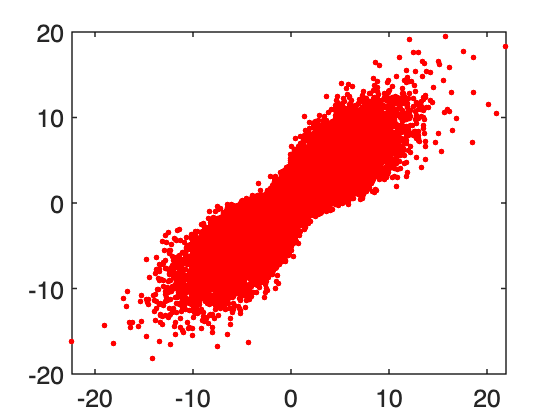

seed = 100;
K = 16;
V = K;
M_Tot = 2;
N = 200000;
Acond = 5;
SNR = 999+1/1;

iva1 = sim_basic_IVA(seed,K,V,M_Tot,N,Acond,SNR);

plot(iva1.Y{1}(end,:)',iva1.Y{2}(end,:)','.r')

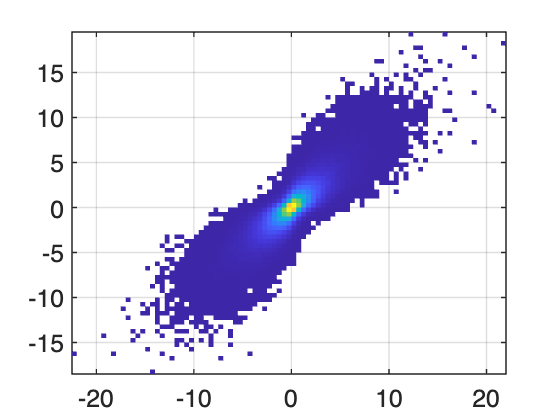

h = histogram2(iva1.Y{1}(end,:)',iva1.Y{2}(end,:)','DisplayStyle','tile','Normalization','pdf');

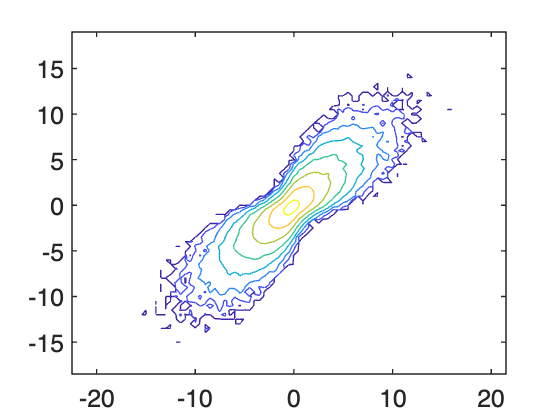

vals = h.Values;
x = h.XBinEdges(1:(end-1));
y = h.YBinEdges(1:(end-1));
[X,Y] = meshgrid(x,y);
contour(X',Y',log10(log10(vals+1)))

corr(iva1.Y{1}(end,:)',iva1.Y{2}(end,:)')

ans = 0.8417

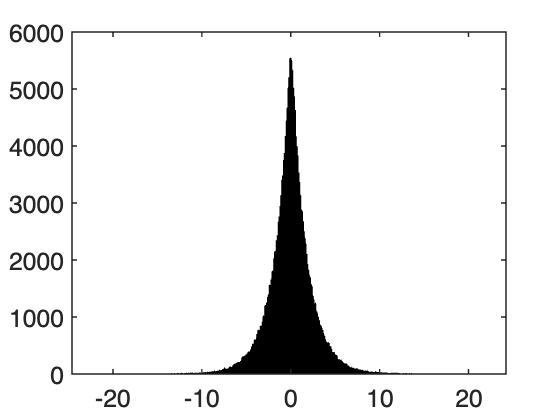


histogram(iva1.Y{1}(end,:)')

Association between subspaces should be 0:

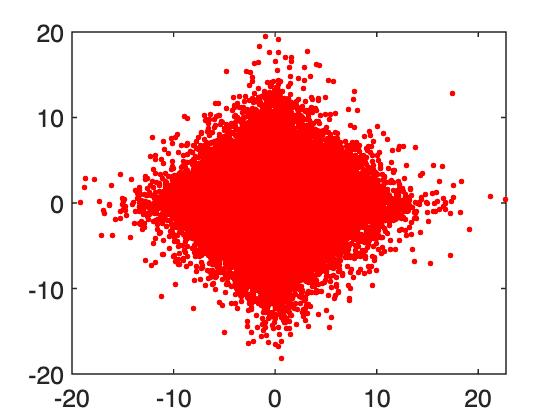

plot(iva1.Y{1}(1,:)',iva1.Y{2}(end,:)','.r')

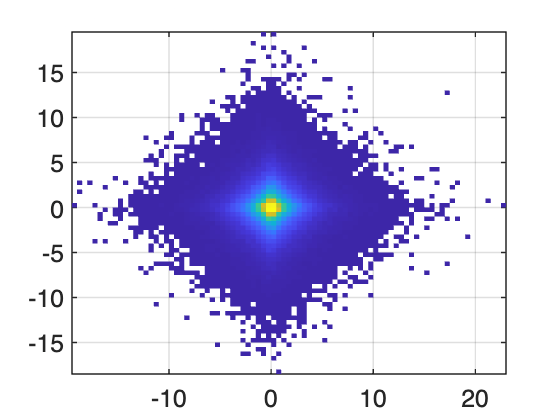

h = histogram2(iva1.Y{1}(1,:)',iva1.Y{2}(end,:)','DisplayStyle','tile','Normalization','pdf');

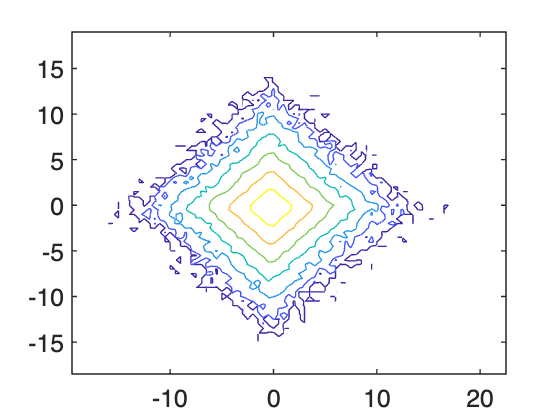

vals = h.Values;
x = h.XBinEdges(1:(end-1));
y = h.YBinEdges(1:(end-1));
[X,Y] = meshgrid(x,y);
contour(X',Y',log10(log10(vals+1)))

corr(iva1.Y{1}(1,:)',iva1.Y{2}(end,:)')

ans = 0.0017

Using gsd class directly:

seed = 100;
num_obs = 50; % 500 5000 50000;
total_datasets = 2;
num_subspaces = 16; % 32 64 128

% Subspace Assignment Matrix (SAM)
SAM = num2cell(repmat((1:num_subspaces)', 1, total_datasets));
num_sources = [];
for mm = 1:total_datasets
    num_sources = [num_sources sum([SAM{:,mm}] ~= 0)];
end

% Define parameters for subspace distributions
half_ns = num_subspaces/2;
max_subspace_corr = [linspace(.1,.7,half_ns),linspace(.2,.8,half_ns)]';
subspace_std = 2.^[linspace(2,-3,half_ns),linspace(-3,2,half_ns)]';
for kk = 1:K
    dist_params(kk).name = 'gcp';
    dist_params(kk).mu   = zeros(sum([SAM{kk,:}] ~= 0),1);
    dist_params(kk).CORR = max_subspace_corr(kk); % Ignored for ICA
    % Define parameters for marginal distributions
    marginal_names = ['laplace', 'logistic', 'normal', 'uniform', 'bimodal_gamma'];
    nn = 1;
    for cc = 1:length(dist_params(kk).mu)
        dist_params(kk).gcp_marginals(cc).name = marginal_names(nn);
        dist_params(kk).gcp_marginals(cc).mu = dist_params(kk).mu(cc);
        switch(lower(dist_params(kk).gcp_marginals(cc).name))
            case 'laplace'
                dist_params(kk).gcp_marginals(cc).sd = subspace_var(kk); % pi/sqrt(3);
            case 'logistic'
            case 'normal'
            case 'uniform'
            case 'bimodal_gamma'
            otherwise
                error('Invalid distribution name.');
        end
        
        if nn < length(marginal_names)
            nn = nn + 1;
        else
            nn = 1;
        end
    end
end
data_dim = num_sources;

% Marginal_distribution = laplace, logistic, uniform, bimodal? (group_difference), mismatched (NEW!)

% Num_sources_estiamted = (.5:.25:1.5) * num_sources